% 21
syms x y;
I=int(int(f,y,(1-x^2)/2,sqrt(1-x^2)),x,0,1)

$$I = \int_{0}^{1}\int_{\frac{1}{2}-\frac{x^{2}}{2}}^{\sqrt{1-x^{2}}}f\left(x,y\right)\mathrm{d}y\mathrm{d}x$$


y1=(1-x^2)/2

$$y1 = \frac{1}{2}-\frac{x^{2}}{2}$$

y2=sqrt(1-x^2)

$$y2 = \sqrt{1-x^{2}}$$

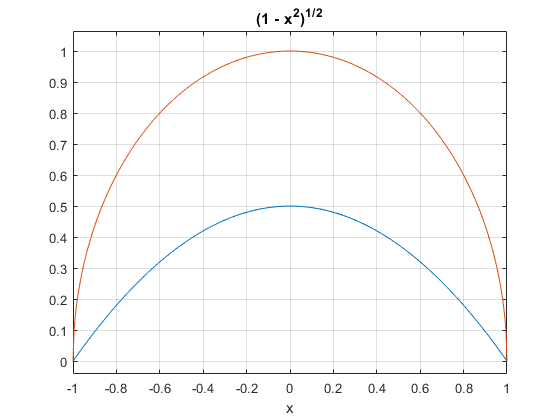


ezplot(y1)
hold on
ezplot(y2)
hold off
grid on



x1=-sqrt(1-y^2)

$$x1 = -\sqrt{1-y^{2}}$$

x2=sqrt(1-y^2)

$$x2 = \sqrt{1-y^{2}}$$

x3=-sqrt(1-2*y)

$$x3 = -\sqrt{1-2\,y}$$

x4=sqrt(1-2*y)

$$x4 = \sqrt{1-2\,y}$$


I1=int(int(f(x,y),x,-sqrt(1-y^2),sqrt(1-y^2)),y,1/2,1)

$$I1 = \int_{\frac{1}{2}}^{1}\int_{-\sqrt{1-y^{2}}}^{\sqrt{1-y^{2}}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y$$

I2=int(int(f(x,y),x,-sqrt(1-y^2),-sqrt(1-2*y)),y,0,1/2)

$$I2 = \int_{0}^{\frac{1}{2}}\int_{-\sqrt{1-y^{2}}}^{-\sqrt{1-2\,y}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y$$

I3=int(int(f(x,y),x,sqrt(1-2*y),sqrt(1-y^2)),y,0,1/2)

$$I3 = \int_{0}^{\frac{1}{2}}\int_{\sqrt{1-2\,y}}^{\sqrt{1-y^{2}}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y$$

IR=I1+I2+I3

$$IR = \begin{array}{l} \int_{0}^{\frac{1}{2}}\int_{\sqrt{1-2\,y}}^{\sigma_{1}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y+\int_{0}^{\frac{1}{2}}\int_{-\sigma_{1}}^{-\sqrt{1-2\,y}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y+\int_{\frac{1}{2}}^{1}\int_{-\sigma_{1}}^{\sigma_{1}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y\\ \mathrm{where}\\ \sigma_{1}=\sqrt{1-y^{2}} \end{array}$$

% 22
syms x y f(x,y);
I=int(int(f,y,0,sin(x)),x,0,pi)

$$I = \int_{0}^{\pi }\int_{0}^{\sin\left(x\right)}f\left(x,y\right)\mathrm{d}y\mathrm{d}x$$


y1=sin(x)

$$y1 = \sin\left(x\right)$$

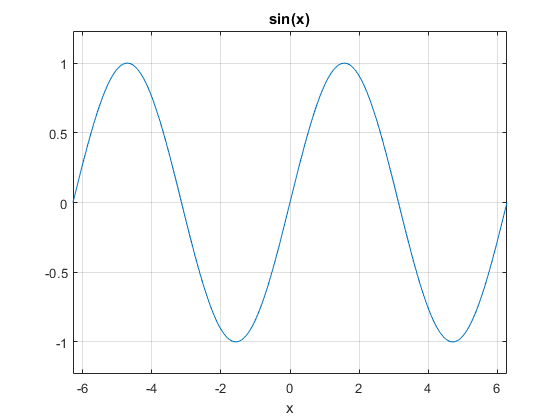


ezplot(y1)
grid on


x1=asin(y)

$$x1 = \mathrm{asin}\left(y\right)$$


IR=int(int(f,x,asin(y),pi-asin(y)),y,0,1)

$$IR = \int_{0}^{1}\int_{\mathrm{asin}\left(y\right)}^{\pi -\mathrm{asin}\left(y\right)}f\left(x,y\right)\mathrm{d}x\mathrm{d}y$$

% 23
syms x y f(x,y);
I=int(int(f,x,3*y/4,sqrt(25-y^2)),y,0,4)

$$I = \int_{0}^{4}\int_{\frac{3\,y}{4}}^{\sqrt{25-y^{2}}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y$$


x1=3*y/4

$$x1 = \frac{3\,y}{4}$$

x2=sqrt(25-y^2)

$$x2 = \sqrt{25-y^{2}}$$

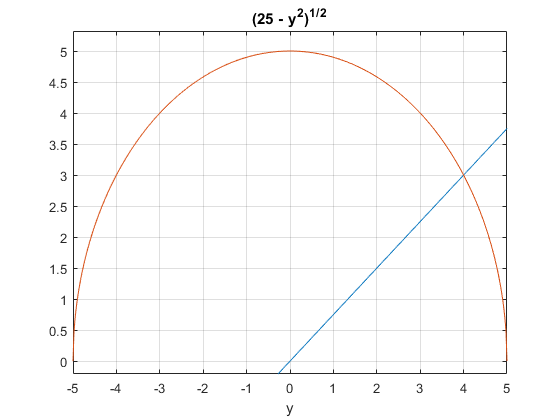


ezplot(x1)
hold on
ezplot(x2)
hold off
grid on


I1=int(int(f,y,0,4*x/3),x,0,3)

$$I1 = \int_{0}^{3}\int_{0}^{\frac{4\,x}{3}}f\left(x,y\right)\mathrm{d}y\mathrm{d}x$$

I2=int(int(f,y,0,sqrt(25-x^2)),x,3,5)

$$I2 = \int_{3}^{5}\int_{0}^{\sqrt{25-x^{2}}}f\left(x,y\right)\mathrm{d}y\mathrm{d}x$$

I=I1+I2

$$I = \int_{0}^{3}\int_{0}^{\frac{4\,x}{3}}f\left(x,y\right)\mathrm{d}y\mathrm{d}x+\int_{3}^{5}\int_{0}^{\sqrt{25-x^{2}}}f\left(x,y\right)\mathrm{d}y\mathrm{d}x$$

% 24
syms x y f(x,y);
I=int(int(f,x,y,sqrt(y)),y,0,9/16)+...
    int(int(f,x,y,3/4),y,9/16,3/4)

$$I = \int_{\frac{9}{16}}^{\frac{3}{4}}\int_{y}^{\frac{3}{4}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y+\int_{0}^{\frac{9}{16}}\int_{y}^{\sqrt{y}}f\left(x,y\right)\mathrm{d}x\mathrm{d}y$$


x1=y

$$x1 = y$$

x2=sqrt(y)

$$x2 = \sqrt{y}$$

x3=3/4

x3 =    0.750000000000000


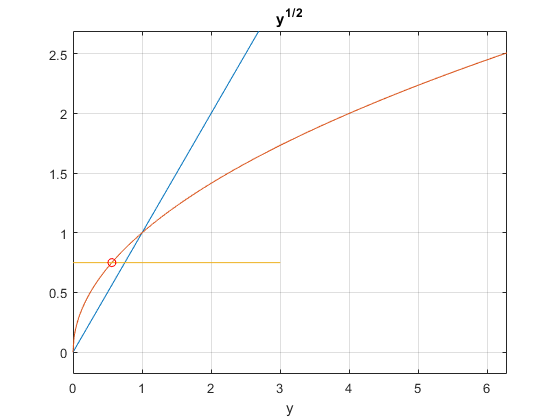


ezplot(x1)
hold on
ezplot(x2)
plot([-1 3],[3/4 3/4])
plot(9/16,3/4,'ro')
hold off
grid on


y1=x

$$y1 = x$$

y2=x^2

$$y2 = x^{2}$$


IR=int(int(f,y,x^2,x),x,0,3/4)

$$IR = \int_{0}^{\frac{3}{4}}\int_{x^{2}}^{x}f\left(x,y\right)\mathrm{d}y\mathrm{d}x$$

% 25
syms x y f(x,y);
I=int(int(f,y,0,sqrt(x)),x,0,2)+...
    int(int(f,y,sqrt(x-2),sqrt(x)),x,2,4)+...
    int(int(f,y,sqrt(x-2),2),x,4,6)

$$I = \int_{0}^{2}\int_{0}^{\sqrt{x}}f\left(x,y\right)\mathrm{d}y\mathrm{d}x+\int_{2}^{4}\int_{\sqrt{x-2}}^{\sqrt{x}}f\left(x,y\right)\mathrm{d}y\mathrm{d}x+\int_{4}^{6}\int_{\sqrt{x-2}}^{2}f\left(x,y\right)\mathrm{d}y\mathrm{d}x$$


y1=sqrt(x)

$$y1 = \sqrt{x}$$

y2=sqrt(x-2)

$$y2 = \sqrt{x-2}$$

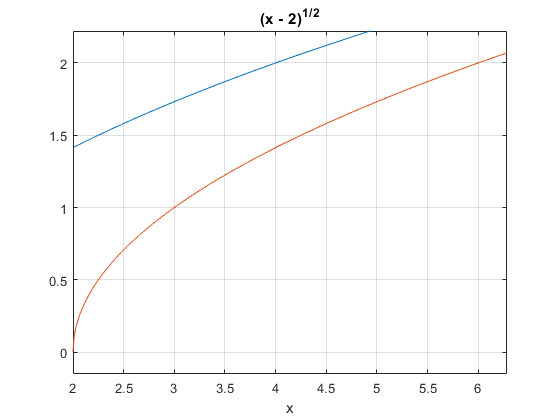


ezplot(y1)
hold on
ezplot(y2)
hold off
grid on


x1=y^2

$$x1 = y^{2}$$

x2=y^2+2

$$x2 = y^{2}+2$$


IR=int(int(f,x,y^2,y^2+2),y,0,2)

$$IR = \int_{0}^{2}\int_{y^{2}}^{y^{2}+2}f\left(x,y\right)\mathrm{d}x\mathrm{d}y$$